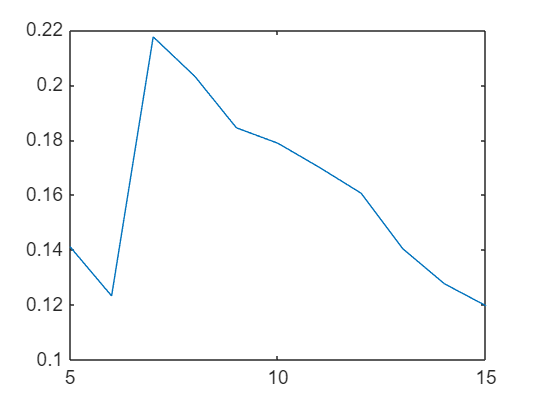

%Definizioni
velocita_seriale= 1000000; 
seriali_disponibili = serialportlist('available');
if( exist('ser') ) 
    delete(ser);
    clear ser;
end

seriale_micro= seriali_disponibili(end);
ser = serialport(seriale_micro, velocita_seriale,Timeout=10); 
configureTerminator(ser,"CR");

%codice nato per campionare 10 forme d'onda comtemporaneamente
%il codice micro di riferimento è "SiPM"
l = 1000; %lunghezza vettore totale
n_misure = 10; %numero di set di misure
d_misura = l/n_misure; %dimensione singolo set di misura
while(1)
    ser.flush;
    stringa= "w";
    ser.writeline(stringa);
    vect1 = ser.read(l + n_misure, "uint16");
    vect1(1:l) = (vect1(1:l) ./ 2^16)*3.3; %NDTR per ogni set di misura
    %plot di 10 forme d'onda contemporaneamente
    for i = 1:n_misure
        figure(i)
        t = (d_misura) - vect1(l + i); %elemento di shift
        %funzione di matlab per ricostrure vettori circolari
        vect1(1 + d_misura*(i-1):i*d_misura) = circshift(vect1(1 + d_misura*(i-1):i*d_misura), -t-1);

        plot((1: d_misura), vect1(1 + d_misura*(i-1):i*d_misura))
    end
end
delete(ser)
clear("ser")

